# BCI Command Recognition Using Deep Learning

This code uses the dataset generated by the 'create_dataset.mlx' to train a convolutional neural network to recognize a given set of commands.

## Load Speech Commands Data Set

Set `datafolder` to the location of the data. Use `audioDatastore` to create a datastore that contains the file names and the corresponding labels. Use the folder names as the label source. Specify the read method to read the entire audio file. The EEG signals are saved in different channels of .wav files. Each file contains a window around a sample or a background (BG) window.

Here we create two datasets. One for training and validation that is generated from streams taken from 9 people, and also a Test dataset that is showing a new person's stream. 

clear
PathToDatabase = './Dataset/Train/';
datafolder = PathToDatabase;
ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')

ads =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/11/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/11/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/11/1_11.wav'
                               ... and 5654 more
                              }
                      Labels: [11; 11; 11 ... and 5654 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


ads0 = copy(ads);

PathToDatabaseTest = './Dataset/Test/';
datafolderTest = PathToDatabaseTest;
adsTest = audioDatastore(datafolderTest, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')

adsTest =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/11/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/11/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/11/1_11.wav'
                               ... and 412 more
                              }
                      Labels: [11; 11; 11 ... and 412 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


adsTest0 = copy(adsTest);

## Choose Words to Recognize

Specify the commands that you want your model to recognize. We remove all commands that are not in the list. To simplify, all "21" and "22" commands are labeled as "LR" and the same goes for "23" and "24" which are mapped to "UD". Moreover, "BG" stands for background samples.

%commands = categorical(["21","22","23","24"]);
commands = categorical(["LR","UD"]);

isLR = ismember(ads.Labels,categorical(["21","22"]));
ads.Labels(isLR) = categorical("LR");
isUD = ismember(ads.Labels,categorical(["23","24"]));
ads.Labels(isUD) = categorical("UD");


isCommand = ismember(ads.Labels,[commands,"BG"]);
isUnknown = ~ismember(ads.Labels,[commands,"BG"]);

%ads.Labels(isUnknown) = categorical("BG");

ads = subset(ads,isCommand)%|isUnknown);

ads =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_11.wav'
                               ... and 2698 more
                              }
                      Labels: [LR; LR; LR ... and 2698 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


countEachLabel(ads)

ans = 3×2 table
    Label    Count
    _____    _____

     BG      1800 
     LR       450 
     UD       451 



isLR = ismember(adsTest.Labels,categorical(["21","22"]));
adsTest.Labels(isLR) = categorical("LR");
isUD = ismember(adsTest.Labels,categorical(["23","24"]));
adsTest.Labels(isUD) = categorical("UD");

isCommand_test = ismember(adsTest.Labels,[commands,"BG"]);
isUnknown_test = ~ismember(adsTest.Labels,[commands,"BG"]);

%adsTest.Labels(isUnknown_test) = categorical("BG");

adsTest = subset(adsTest,isCommand_test)%|isUnknown_test);

adsTest =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/21/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/21/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Test/21/1_11.wav'
                               ... and 172 more
                              }
                      Labels: [LR; LR; LR ... and 172 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


countEachLabel(adsTest)

ans = 3×2 table
    Label    Count
    _____    _____

     BG       100 
     LR        37 
     UD        38 


## Split Data into Training, Validation, and Test Sets

The data set folder contains text files, which list the audio files to be used as the validation and test sets. We use the supporting function [`splitData`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','splitData.m'))) to randomly split the datastore into training, validation, and test sets with a ratio of 4 to 1 (80%-20%). 

[adsTrain,adsValidation] = splitData(ads,datafolder)

adsTrain =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_1.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_10.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_12.wav'
                               ... and 2261 more
                              }
                      Labels: [LR; LR; LR ... and 2261 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


adsValidation =   audioDatastore with properties:

                       Files: {
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_11.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_14.wav';
                              '/home/bardiabarabadi/MUSE/EEG_Classifier/Dataset/Train/21/1_19.wav'
                               ... and 434 more
                              }
                      Labels: [LR; LR; LR ... and 434 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


## Compute Speech Spectrograms

To prepare the data for efficient training of a convolutional neural network, we convert the speech waveforms to log-mel spectrograms.

Define the parameters of the spectrogram calculation. `segmentDuration` is the duration of each speech clip (in seconds). `frameDuration` is the duration of each frame for spectrogram calculation. `hopDuration` is the time step between each column of the spectrogram. `numBands` is the number of log-mel filters and equals the height of each spectrogram.

Fs = 256;
segmentDuration = 700/Fs;
frameDuration = 150/Fs;
hopDuration = 15/Fs;
numBands = 15;
epsil = 1e-6;

Here, we compute the spectrograms for the training, validation, and test sets by using the supporting function [`speechSpectrograms`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','speechSpectrograms.m'))). The `speechSpectrograms` function uses `designAuditoryFilterBank` for the log-mel spectrogram calculations. To obtain data with a smoother distribution, we take the logarithm of the spectrograms using a small offset `epsil`.

adsTrain.reset();
adsTest.reset();
adsValidation.reset();
error(['Uncomment this to generate spects again. ' ...
    'Otherwise load values using the line below:'])
load('DS.mat', 'XTrain', 'XTest', 'XValidation', ...
    'YTrain','YTest','YValidation');
XTrain = speechSpectrograms(adsTrain,segmentDuration, ...

Computing speech spectrograms...
Processed 100 files out of 2269
Processed 200 files out of 2269
Processed 300 files out of 2269
Processed 400 files out of 2269
Processed 500 files out of 2269
Processed 600 files out of 2269
Processed 700 files out of 2269
Processed 800 files out of 2269
Processed 900 files out of 2269
Processed 1000 files out of 2269
Processed 1100 files out of 2269
Processed 1200 files out of 2269
Processed 1300 files out of 2269
Processed 1400 files out of 2269
Processed 1500 files out of 2269
Processed 1600 files out of 2269
Processed 1700 files out of 2269
Processed 1800 files out of 2269
Processed 1900 files out of 2269
Processed 2000 files out of 2269
Processed 2100 files out of 2269
Processed 2200 files out of 2269
...done


    frameDuration,hopDuration,numBands);
XTrain = log10(XTrain + epsil);

XValidation = speechSpectrograms(adsValidation,segmentDuration, ...

Computing speech spectrograms...
Processed 100 files out of 432
Processed 200 files out of 432
Processed 300 files out of 432
Processed 400 files out of 432
...done


    frameDuration,hopDuration,numBands);
XValidation = log10(XValidation + epsil);

XTest = speechSpectrograms(adsTest,segmentDuration, ...

Computing speech spectrograms...
Processed 100 files out of 175
...done


frameDuration,hopDuration,numBands);
XTest = log10(XTest + epsil);

YTrain = adsTrain.Labels;
YValidation = adsValidation.Labels;
YTest = adsTest.Labels;

YTrain = removecats(YTrain);
YValidation = removecats(YValidation);
YTest = removecats(YTest)

XTest(:,:,5,:)=[];
XValidation(:,:,5,:)=[];
XTrain(:,:,5,:)=[];

save('DS.mat', 'XTrain', 'XTest', 'XValidation', 'YTrain','YTest','YValidation');

## Visualize Data

Plot the waveforms and spectrograms of an example. 

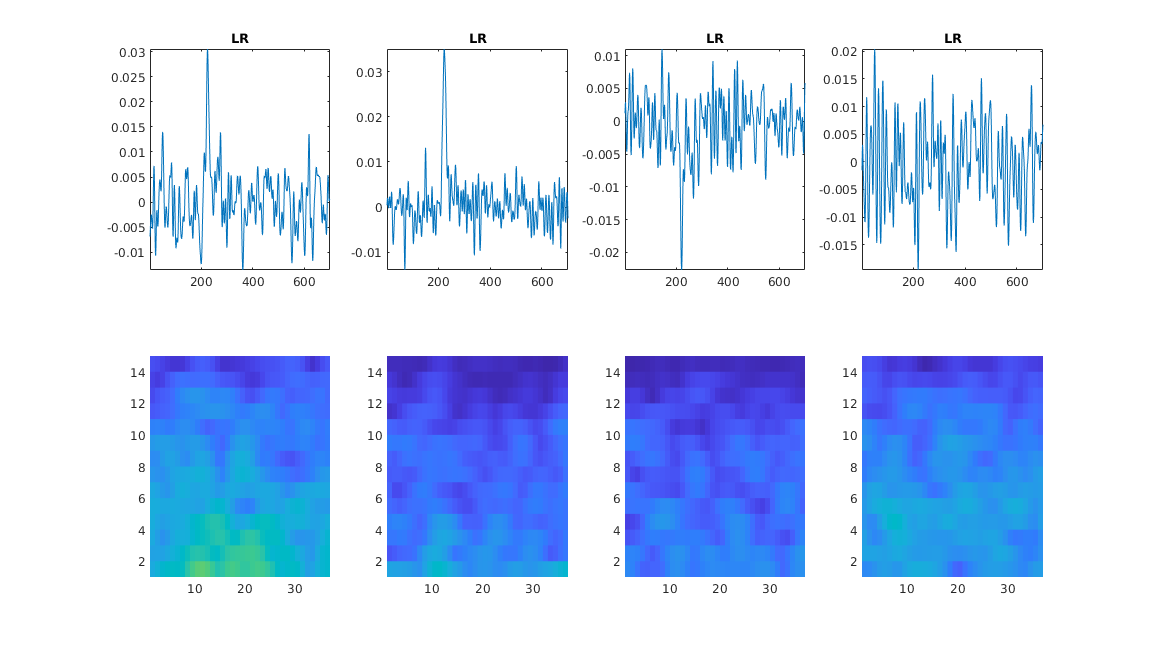

load('DS.mat', 'XTrain', 'XTest', 'XValidation', 'YTrain','YTest','YValidation');
specMin = min(XValidation(:));
specMax = max(XValidation(:));
idx = 11;
figure('Units','normalized','Position',[0.2 0.2 0.6 0.6]);
for i = 1:4
    [x,~] = audioread(adsValidation.Files{idx(1)});
    subplot(2,4,i)
    plot(x(:,i))
    axis tight
    title(string(adsValidation.Labels(idx(1))))
    
    subplot(2,4,i+4)
    spect = XValidation(:,:,i,idx(1));
    pcolor(spect)
    caxis([specMin specMax])
    shading flat
    
end

Training neural networks is easiest when the inputs to the network have a reasonably smooth distribution and are normalized. To check that the data distribution is smooth, plot a histogram of the pixel values of the training data.

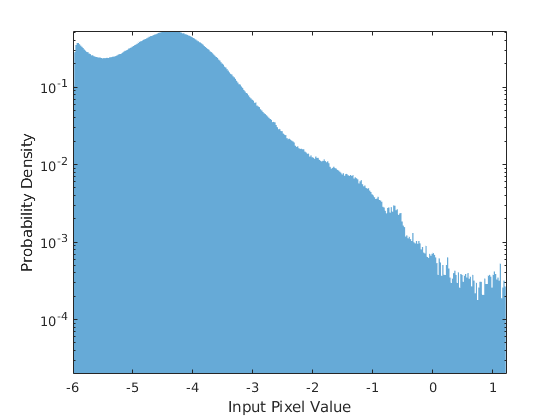

figure
histogram(XTrain,'EdgeColor','none','Normalization','pdf')
axis tight
ax = gca;
ax.YScale = 'log';
xlabel("Input Pixel Value")
ylabel("Probability Density")

Plot the distribution of the different class labels in the training and validation sets. The validation set has a very similar distribution to the validation set.

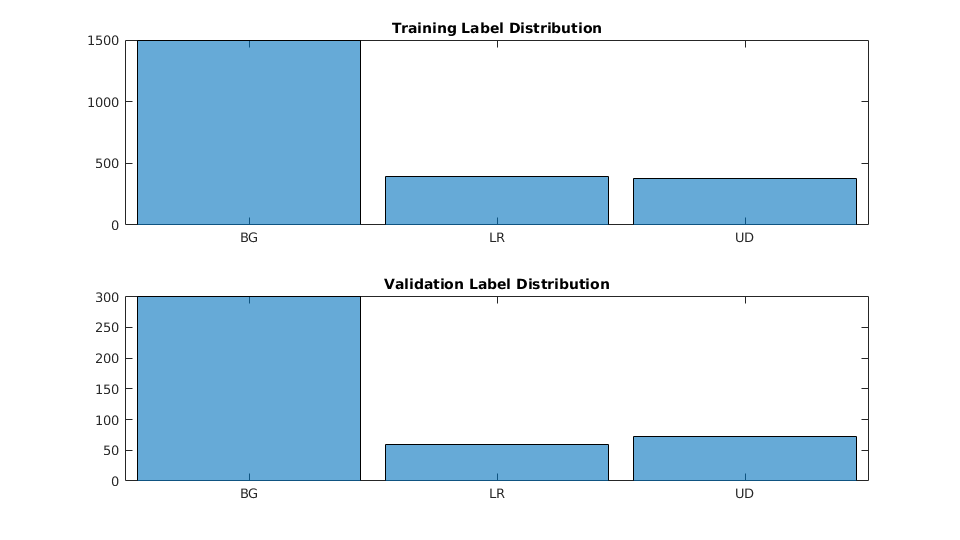

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
subplot(2,1,1)
histogram(YTrain)
title("Training Label Distribution")
subplot(2,1,2)
histogram(YValidation)
title("Validation Label Distribution")

## Add Data Augmentation

Create an augmented image datastore for automatic augmentation and resizing of the spectrograms. Translate the spectrogram randomly up to 5 frames (20 ms) forwards or backwards in time, and scale the spectrograms along the time axis up or down by 10 percent. Augmenting the data can increase the effective size of the training data and help prevent the network from overfitting. The augmented image datastore creates augmented images in real time during training and inputs them to the network. No augmented spectrograms are saved in memory.

sz = size(XTrain);
specSize = sz(1:2);
imageSize = [specSize 4];
augmenter = imageDataAugmenter( ...
    'RandXTranslation',[-5 5], ...
    'RandXScale',[0.9 1.1], ...
    'FillValue',log10(epsil));
augimdsTrain = augmentedImageDatastore(imageSize,XTrain,YTrain, ...
    'DataAugmentation',augmenter)

augimdsTrain =   augmentedImageDatastore with properties:

         NumObservations: 2269
           MiniBatchSize: 128
        DataAugmentation: [1×1 imageDataAugmenter]
      ColorPreprocessing: 'none'
              OutputSize: [15 37]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


## Define Neural Network Architecture

Create a simple network architecture as an array of layers. Use convolutional and batch normalization layers, and downsample the feature maps "spatially" (that is, in time and frequency) using max pooling layers. To reduce the possibility of the network memorizing specific features of the training data, add a small amount of dropout to the input to the last fully connected layer.

The network is small, as it has only four convolutional layers with few filters. `numF` controls the number of filters in the convolutional layers. 

Here we are using a weighted cross entropy classification loss. [`weightedClassificationLayer(classWeights)`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','weightedClassificationLayer.m'))) creates a custom classification layer that calculates the cross entropy loss with observations weighted by `classWeights`. We specify the class weights in the same order as the classes appear in `categories(YTrain)`. To give each class equal total weight in the loss, use class weights that are inversely proportional to the number of training examples in each class. 

classWeights = 1./countcats(YTrain);
classWeights = classWeights'/mean(classWeights)

classWeights =     0.3413    1.3086    1.3500


numClasses = numel(categories(YTrain));

timePoolSize = ceil(imageSize(2)/2);
dropoutProb = 0.1;
numF = 40;
layers = [
    imageInputLayer(imageSize)
    
    convolution2dLayer(1,10,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    convolution2dLayer(3,numF,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    convolution2dLayer(3,numF,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    %maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    convolution2dLayer(3,numF*2,'Padding','same')
    %batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    %convolution2dLayer(3,2*numF,'Padding','same')
    %batchNormalizationLayer
    %reluLayer
    
    %averagePooling2dLayer(3,'Stride',2,'Padding','same')
    
    %convolution2dLayer(3,4*numF,'Padding','same')
    %batchNormalizationLayer
    %reluLayer
    %convolution2dLayer(1,4*numF,'Padding','same')
    %batchNormalizationLayer
    %reluLayer
     
    %averagePooling2dLayer([1 timePoolSize])
    
    dropoutLayer(dropoutProb)
    fullyConnectedLayer(10)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    weightedClassificationLayer(classWeights)];

## Train Network

Specify the training options. Use the Adam optimizer with a mini-batch size of 30. Train for 50 epochs and reduce the learning rate by a factor of 10 after 30 epochs.

miniBatchSize = 30;
validationFrequency = floor(numel(YTrain)/miniBatchSize)*2;
options = trainingOptions('adam', ...
    'InitialLearnRate',3e-3, ...
    'MaxEpochs',50, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',true, ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'LearnRateSchedule','piecewise', ...
    'ValidationPatience',4, ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',30);

Train the network. To load a pretrained network instead of training a network from scratch, set `doTraining` to `false`.

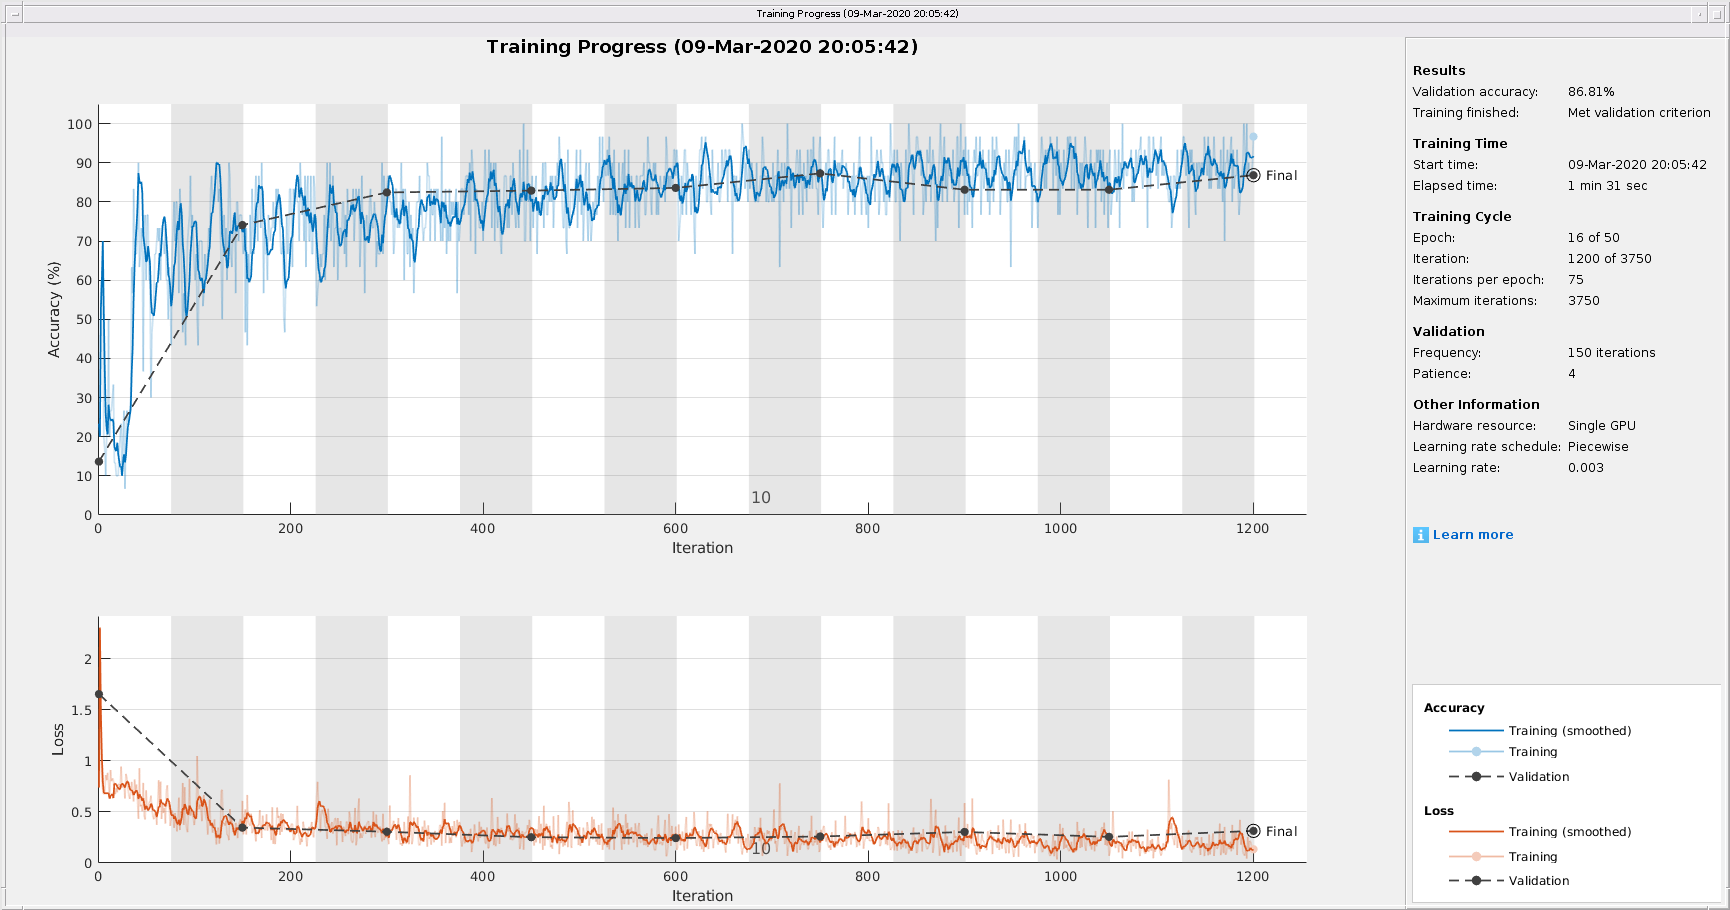

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       23.33% |       13.66% |       0.7386 |       1.6554 |          0.0030 |
|       1 |          50 |       00:00:05 |       60.00% |              |       0.7129 |              |          0.0030 |
|       2 |         100 |       00:00:09 |       63.33% |              |       0.3710 |              |          0.0030 |
|       2 |         150 |       00:00:12 |       70.00% |       74.07% |       0.6091 |   

doTraining = true;
if doTraining
    trainedNet = trainNetwork(augimdsTrain,layers,options); 
    save('commandNet.mat','trainedNet');
else
    load('commandNet.mat','trainedNet');
end

## Evaluate Trained Network

Calculate the final accuracy of the network on the training set (without data augmentation) and validation set. The network is very accurate on this data set. However, the training, validation, and test data all have similar distributions that do not necessarily reflect real-world environments. 

YValPred = classify(trainedNet,XValidation);
validationError = mean(YValPred ~= YValidation);
YTrainPred = classify(trainedNet,XTrain);
trainError = mean(YTrainPred ~= YTrain);
disp("Training error: " + trainError*100 + "%")

Training error: 8.7263%


disp("Validation error: " + validationError*100 + "%")

Validation error: 13.1944%



YTestPred = classify(trainedNet,XTest);
testError = mean(YTestPred ~= YTest);
disp("Test error: " + testError*100 + "%")

Test error: 26.2857%


Plot the confusion matrix. Display the precision and recall for each class by using column and row summaries. 

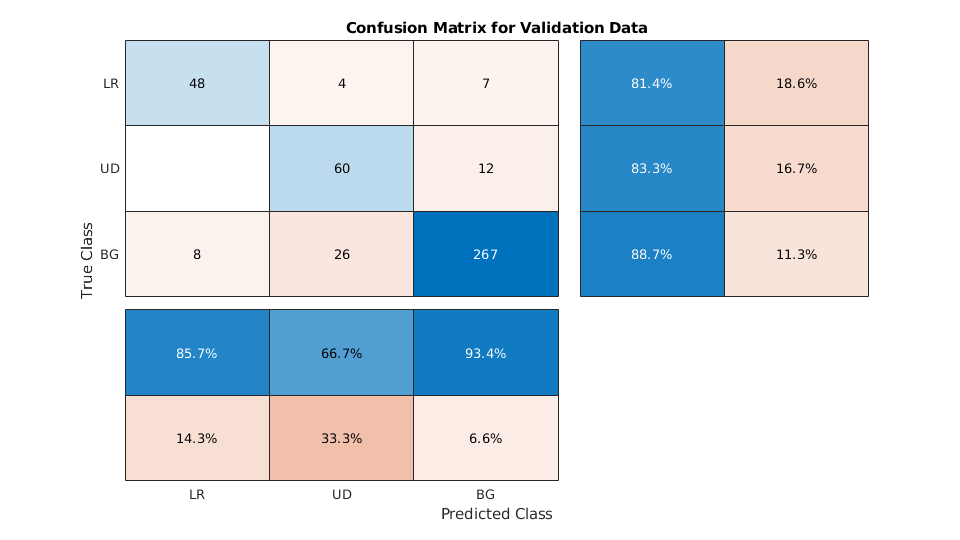

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
cm = confusionchart(YValidation,YValPred);
cm.Title = 'Confusion Matrix for Validation Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
sortClasses(cm, [commands,"BG"])

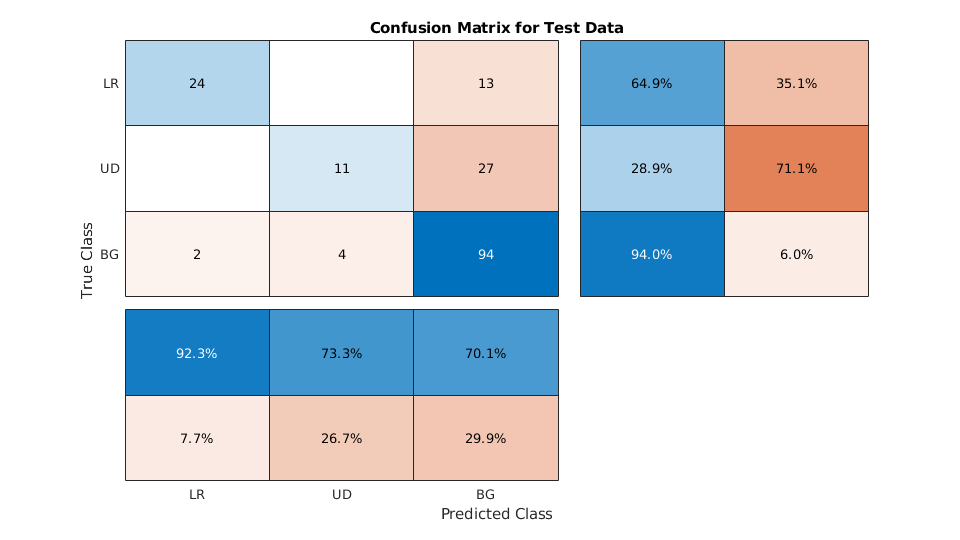


figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
cm = confusionchart(YTest,YTestPred);
cm.Title = 'Confusion Matrix for Test Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';
sortClasses(cm, [commands,"BG"])

Now we compute the total size of the network in kilobytes and test its prediction speed when using a CPU. The prediction time is the time for classifying a single input image. 

info = whos('trainedNet');
disp("Network size: " + info.bytes/1024 + " kB")

Network size: 345.6729 kB



for i=1:100
    x = randn(imageSize);
    tic
    [YPredicted,probs] = classify(trainedNet,x,"ExecutionEnvironment",'cpu');
    time(i) = toc;
end
disp("Single-image prediction time on CPU: " + mean(time(11:end))*1000 + " ms")

Single-image prediction time on CPU: 3.9648 ms
